# Optimización unidimensional usando búsqueda dicotómica en MATLAB

**Profesor:** PhD. Marlon E. Moscoso Martínez

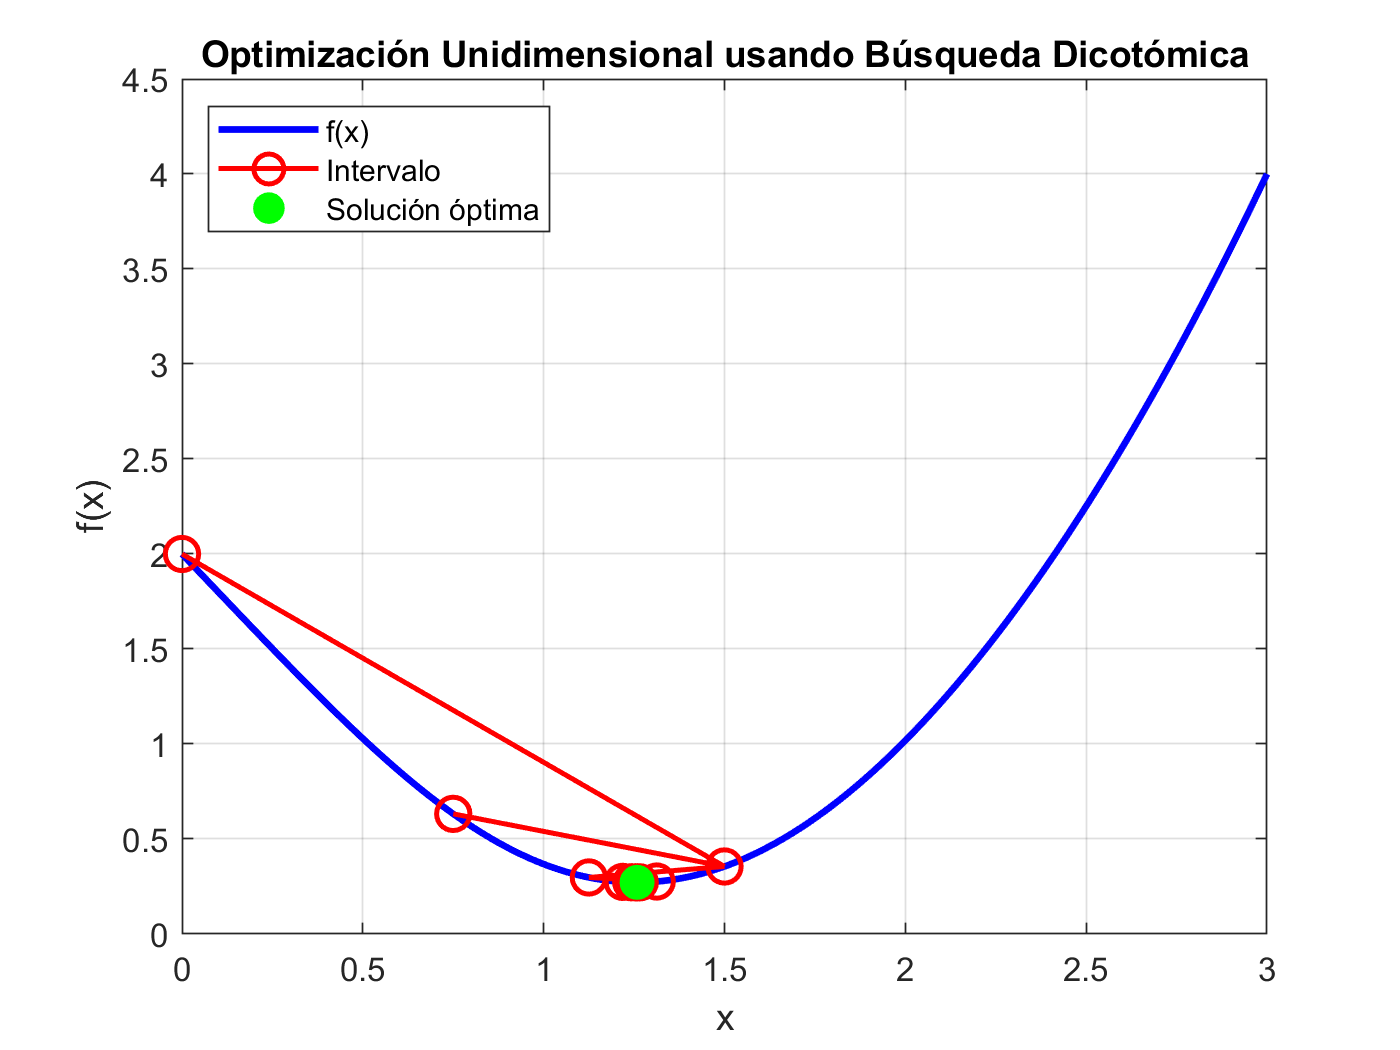

% Limpieza de la consola, variables y figuras
clc; clear; close all;

% Definir la función objetivo
f = @(x) (x-1).^2 + exp(-x.^2);  % Función unimodal

% Definir los límites del intervalo de búsqueda
a = 0;
b = 3;

% Parámetros de la búsqueda dicotómica
delta = 1e-6;  % Tolerancia (delta)
epsilon = delta / 10;  % Distancia entre los puntos (epsilon < delta)

% Inicialización de las variables
iter = 0;  % Contador de iteraciones
max_iter = 100;  % Número máximo de iteraciones

% Graficar la función objetivo
x_vals = linspace(a, b, 1000);
y_vals = f(x_vals);
figure;
plot(x_vals, y_vals, 'b-', 'LineWidth', 2);
hold on;
xlabel('x');
ylabel('f(x)');
title('Optimización Unidimensional usando Búsqueda Dicotómica');
grid on;

% Bucle para realizar la búsqueda dicotómica
while (b - a) > delta && iter < max_iter
    iter = iter + 1;
    
    % Paso 2: Calcular los dos puntos cercanos al punto medio
    x1 = (a + b) / 2 - epsilon / 2;
    x2 = (a + b) / 2 + epsilon / 2;
    
    % Paso 3: Evaluar la función en los puntos x1 y x2
    f1 = f(x1);
    f2 = f(x2);
    
    % Paso 4: Actualizar el intervalo
    if f1 < f2
        b = x2;  % Reducir el límite superior
    else
        a = x1;  % Reducir el límite inferior
    end
    
    % Mostrar gráficamente el intervalo actual
    plot([a b], [f(a) f(b)], 'ro-', 'MarkerSize', 10, 'LineWidth', 1.5);
    pause(0.3);  % Pausar para visualizar la evolución
end

% Definir la solución óptima final
x_opt = (a + b) / 2;
f_opt = f(x_opt);

% Marcar la solución óptima en el gráfico
legend('f(x)', 'Intervalo','Location','northwest');
plot(x_opt, f_opt, 'go', 'MarkerSize', 10, 'MarkerFaceColor', 'g', 'DisplayName', 'Solución óptima');
hold off;


% Mostrar los resultados
disp('Punto óptimo (x):');

Punto óptimo (x):


disp(x_opt);

    1.2583



disp('Valor óptimo de f(x):');

Valor óptimo de f(x):


disp(f_opt);

    0.2720

